# Properties of Pure Substances 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

The state of a pure substance can be tracked by its values of state variables such as temperature, pressure, and volume. The challenge for many humans is understanding the interactions between these values as the dimension of the state space is higher than we usually tend to visualize. The basic states of matter are solid, liquid, and gas, but the boundaries between these states are of interest in thermodynamics. At what temperatures, pressures, and volumes can a substance coexist as both liquid and vapor? Or liquid and solid? Are there values where the substance will sublimate between solid and gas? 

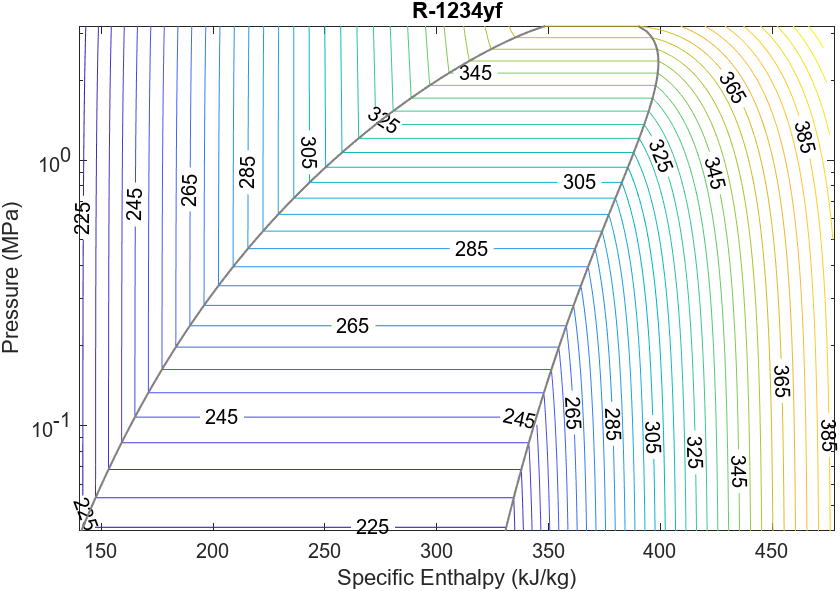

Property tables and property diagrams contain information about the thermodynamic properties of a substance.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

## Creating State Diagrams

Pure substances exist in different states of matter depending on the temperature and pressure of the environment. A standard shape for such temperature/pressure diagrams is given below.  You can select different substances. The data was retrieved from [CoolProp](http://www.coolprop.org/). [1]

optSD = ["Make a Selection" "Water" "n-Propane" "Oxygen" "Methanol"];
firstSubstance = optSD(2);

fig1 = drawThreePhasePlot(firstSubstance);

 **Reflect**. You may note that the water diagram has a strange shape. What do you know about the density of water in its frozen state instead of in its liquid state?

## Variation Within a State

There are many finer gradations among states of matter that you will learn about over time. One example, the six known phases of solid oxygen that exhibit different colors, conduction, and crystalline structures, is shown in Figure 1.

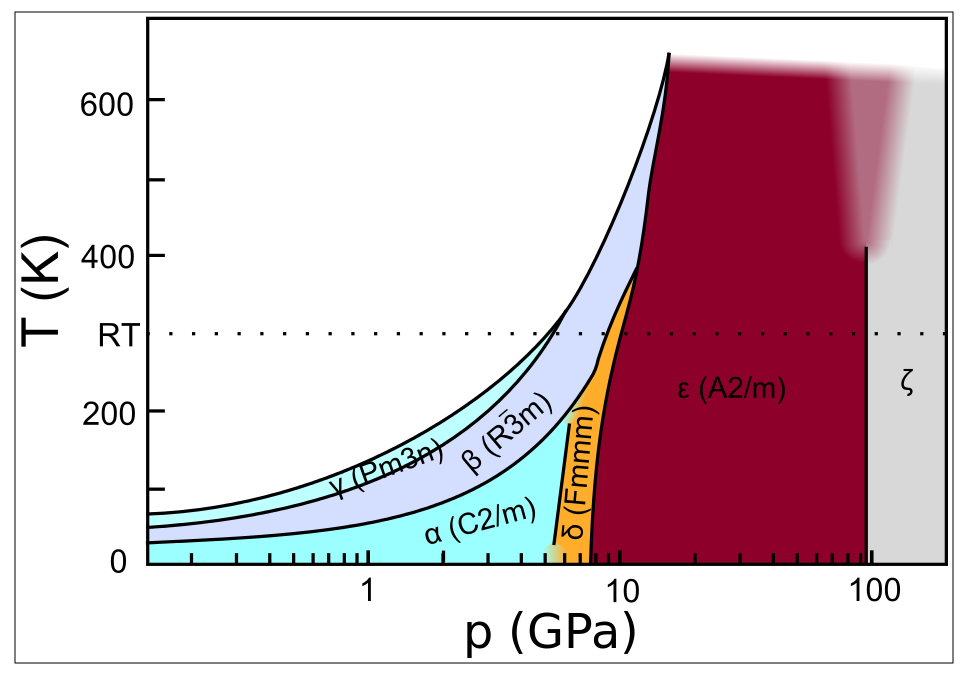

Figure 1: Six states of solid oxygen. 

Image credit: Kaligula, [CC BY-SA 3.0](https://creativecommons.org/licenses/by-sa/3.0), via [Wikimedia Commons](https://commons.wikimedia.org/wiki/File:Phase_diagram_of_solid_oxygen.svg)

## And Blurring Between States

In Figure 1, there is a blurring between the $\epsilon$ and $\zeta$ states at high pressure and above about 400 K. If you look closely, there is a similar blurring between the $\alpha$ and $\delta$ states at low temperature between about 5 and 6 GPa. This visual depiction attempts to capture a physical phenomenon.  For instance, the phase change indicated by a discontinuity in the specific volume between the liquid and vapor states disappears at temperatures and pressures above the critical temperature and pressure. We call this state a supercritical fluid when it is above both the critical temperature and the critical pressure. Below the critical temperature, we call it a compressible liquid, and below the critical pressure, we call it a gas. 

optSD = ["Make a Selection" "Water" "n-Propane" "Oxygen" "Methanol"];
firstSubstance = optSD(2);
clear fig1
fig2 = drawThreePhasePlot(firstSubstance,1);

**Note: **The terminology of a *critical point* comes from the mathematical study of dynamical systems. Remember that a critical point of a function is a point in the domain where the derivative is zero (or the function is not differentiable). In thermodynamics, the critical point of a substance is the point where the rates of change of variables in state space become zero.

## Quality

We have chosen only two state variables to consider in the state diagrams above: pressure and temperature. Because the actual state space is a higher-dimensional surface, we could choose a different pair of state variables to consider, such as enthalpy. Enthalpy is defined as $H = U+PV$, where $U$ is the internal energy of the system and $PV$ is the product of the pressure and the volume. 

## Creating Temperature/Entropy Plots

opts = ["Make a Selection" "Water" "R134a" "n-Propane" "Benzene" "Ammonia" "Methanol"];
clear fig2 fig1
substance = opts(2);

Define the figure, axis, and label, then plot the liquid/vapor critical point. 

if substance == opts(1)
    warning("Please select a substance.")
    disp("Using water as a default selection.")
    substance = "Water";
end
    [yRangeVals, Tisobaric, Tisometric, ScAll, Tc, Pc, Sc, Smin, Smax,TisobaricCritical,S] = loadData(substance);

ax = createFigure(substance,yRangeVals,Smin,Smax);

% Plot the critical point:
hold on
critPtPlot = scatter(ax, Sc, Tc, 30, 'o', "filled", "SeriesIndex", 1);
hold off
legend("Critical Point")

### Plot the quality curve

The quality curves range from the fully saturated liquid boundary, with a quality of 0, to the fully saturated vapor boundary, with a quality of 1. 

[Tsat, qualityCurves, qualityCurvePlot] = drawQualityCurves(yRangeVals, Tc, ax, ScAll);

### Plot the isobaric processes line

At constant pressure, as the entropy increases, the temperature also increases outside of the two-phase region. Inside the two-phase region, the increase in entropy is entirely due to the increasing quantity of vapor and decreasing quantity of liquid, so the temperature stays constant. This is why the liquid-vapor boundary was a single line in the initial phase plot shown above.

[isobaricCurves, isobaricPlot] = drawIsobaricLines(substance, ax, Tisobaric,S);

### Plot the isometric processes line

The changes are less dramatic at a constant volume across the two-phase region, but distinctions are still visible. 

[isometricCurves, isometricPlot] = drawIsometricLines(substance, ax, Tisometric,S);

showCriticalPoint = true; showQualityCurves = true; showIsobaric = true; showIsometric = true;
updateMyLegend(ax,showCriticalPoint, critPtPlot, showQualityCurves, qualityCurves, ...
    showIsometric, isometricCurves, showIsobaric, isobaricCurves);

### ** Exercise.**

After visualizing the state plots, it is important to check that you understand what they are telling you.

if ~exist("substance","var") || substance == "Benzene" || substance == "Make a Selection"
    newopts = ["Water" "R134a" "n-Propane" "Ammonia" "Methanol"];
    substance = newopts(randi(5));
    [yRangeVals, ~, ~, ScAll, Tc, ~, Sc, Smin, Smax,TisobaricCritical,S] = loadData(substance);
    Tsat = linspace(yRangeVals(1), Tc, 100);
end
if substance == "n-Propane" || substance == "R134a"
    myName = substance;
else
    myName = lower(substance);
end
stateOpts = ["liquid" "supercritical" "two-phase" "gaseous"];
myState = stateOpts(randi(length(stateOpts)));
 
flag = 0;
axNew = identifyRegions(substance, yRangeVals, Smin, Smax, ScAll, Tsat, Sc, Tc, S,TisobaricCritical);
displayFormula(["'In which regions is the '", myName, "' in a '",myState,"' state?'"]) 

What do you see on the plot?

myAnswer = "l2"; 
if ~exist("flag","var")
    disp("You must reset the question before continuing.")
elseif flag == 0
    flag = flag + 1;
    myAnswer = "none";
end

checkExercise1(myAnswer,myState,myName,substance,yRangeVals,Smin,Smax,ScAll,Tsat,Sc,Tc,S,TisobaricCritical)

## References

[1]  Bell, I. H., Wronski, J., Quoilin, S., & Lemort, V. (2013). Pure and Pseudo-pure Fluid Thermophysical Property Evaluation and the Open-Source Thermophysical Property Library CoolProp. *Industrial & Engineering Chemistry Research*, *53*(6), 2498-2508. https://doi.org/10.1021/ie4033999

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Helper Functions

function ax = createFigure(substance,yRangeVals,Smin,Smax)

figure
title("Temperature-Entropy plot of "+substance)
xlabel("Entropy s (J/kg)")
ylabel("Temperature T (K)")
hold on

ylim(yRangeVals) 
if substance == "Benzene"
    xlim([Smin, 1.2*Smax])
else
    xlim([Smin Smax])
end
ax = gca;
hold off
end

function incorrectExercise1Feedback(myAnswer,myState,myName,substance)
if contains(myAnswer,"l")
    disp("No, "+myName+" is not " + myState + " in Region I, is a liquid.")
elseif contains(myAnswer,"2")
    disp(substance + " is not " + myState + " in Region II, it is two-phase.")
    disp("In Region II the quality of the substance tracks the ratio between liquid and gas.")
elseif contains(myAnswer,"g")
    disp("No, "+myName + " is not " + myState + " in Region III, it is a gas.")
elseif contains(myAnswer,"c")
    disp("No, "+myName + " is not " + myState + " in Region IV, it is a supercritical fluid.")
elseif contains(myAnswer,"5")
    disp("No, "+myName + " is not " + myState + " in Region V, it is a gas.")
end
end

function checkExercise1(myAnswer,myState,myName,substance, yRangeVals, Smin, Smax, ScAll, Tsat, Sc, Tc,S,TisobaricCritical)
if myAnswer == "none"
    disp("Please select a region or set of regions. The "+myName+" is "+myState+" in one or more regions.")
else
    switch myState
        case "liquid"
            if myAnswer == "l2"
                disp("Correct! The " + myName + " is "+myState+ " in both Region I and Region II.")
                disp("Region I is only liquid and Region II is two-phase: both liquid and gaseous.")
                ax2 = identifyRegions(substance, yRangeVals, Smin, Smax, ScAll, Tsat, Sc, Tc,S,TisobaricCritical);
                hold on
                area(ax2,[Smin Sc],[Tc Tc],"SeriesIndex",4,"FaceAlpha",0.4)
                area(ax2,ScAll{:,end},Tsat,"SeriesIndex",4,"FaceAlpha",0.4)
                hold off
                legend off
            elseif contains(myAnswer,"l")
                disp("Yes, "+myName+" is a liquid in Region I, but it is also a noncritical liquid in another region.")
            elseif contains(myAnswer,"2")
                disp("Yes, "+myName+" is both liquid and gas in Region II, but it is also a noncritical "+myState+" in another region.")
            else
                incorrectExercise1Feedback(myAnswer,myState,myName)
            end
        case "two-phase"
            if myAnswer == "2"
                disp("Correct! The " + myName + " is two-phase in Region II: both liquid and vapor.")
                ax2 = identifyRegions(substance, yRangeVals, Smin, Smax, ScAll, Tsat, Sc, Tc,S,TisobaricCritical);
                hold on
                area(ax2,ScAll{:,1},Tsat,"SeriesIndex",3,"FaceAlpha",0.4)
                area(ax2,ScAll{:,end},Tsat,"SeriesIndex",3,"FaceAlpha",0.4)
                hold off
                legend off
            elseif contains(myAnswer,"2")
                firstBit = extractBefore(myAnswer,"2");
                lastBit = extractAfter(myAnswer,"2");
                incorrectExercise1Feedback(firstBit+lastBit,myState,myName)
            else
                incorrectExercise1Feedback(myAnswer,myState,myName)
            end
        case "gaseous"
            if myAnswer == "2g5"
                disp("Correct! The " + myName + " is "+myState+ " in Region II, Region III, and Region V.")
                disp("Region III and Region V are only gaseous and Region II is two-phase: both liquid and gaseous.")
                ax2 = identifyRegions(substance, yRangeVals, Smin, Smax, ScAll, Tsat, Sc, Tc,S,TisobaricCritical);
                hold on
                % area(ax2,[Sc,ax2.XLim(2)],[Tc Tc],"SeriesIndex",4,"FaceAlpha",0.4)
                % area(ax2,ScAll{:,1},Tsat,"SeriesIndex",4,"FaceAlpha",0.4)
                % hold off
                cmap = colormap;
                x1 = ax2.XLim(1);
                x2 = ax2.XLim(2);
                y1 = ax2.YLim(1);
                y2 = ax2.YLim(2);
                SB = S(isfinite(TisobaricCritical));
                TB = TisobaricCritical(isfinite(TisobaricCritical));
                idx1 = find(SB>Sc,1,"first");
                idx2 = find(TB<y2,1,"last");
                fill(ax2,[x1 (ScAll{:,1})' Sc SB(idx1:idx2) SB(idx2+1) x2 x2],...
                    [y1 Tsat Tc TB(idx1:idx2)' y2 y2 y1],cmap(2,:),"FaceAlpha",0.4)
                hold off
                legend off
            elseif myAnswer == "2g"
                disp("Yes, "+myName+" is a gas in both Region II and Region III, but there is still one more.")
            elseif myAnswer == "g5"
                disp("Yes, "+myName+" is a gas in both Region III and Region V, but there is still one more.")
            elseif myAnswer == "g"
                disp("Yes, "+myName+" is a gas in Region III, but it is also gaseous in other regions.")
            elseif myAnswer == "2"
                disp("Yes, "+myName+" is both liquid and gas in Region II, but it is also a "+myState+" in other regions.")
            elseif myAnswer == "5"
                disp("Yes, "+myName+" is a gaseous in Region V, but it is also gaseous in other regions.")
            else
                myAnswer = erase(myAnswer,"2");
                myAnswer = erase(myAnswer,"g");
                myAnswer = erase(myAnswer,"5");
                if myAnswer == ""
                    warning("How did you get here?")
                else
                incorrectExercise1Feedback(myAnswer,myState,myName)
                end
            end
        case "supercritical"
            if myAnswer == "c"
                disp("Correct! The " + myName + " is supercritical in Region IV.")
                disp("The distinctions between liquid and gas disappear.")
                disp("We say that Region IV is a supercritical fluid.")
                ax2 = identifyRegions(substance, yRangeVals, Smin, Smax, ScAll, Tsat, Sc, Tc,S,TisobaricCritical);
                hold on
                cmap = colormap;
                x1 = ax2.XLim(1);
                x2 = ax2.XLim(2);
                y2 = ax2.YLim(2);
                SB = S(isfinite(TisobaricCritical));
                TB = TisobaricCritical(isfinite(TisobaricCritical));
                idx1 = find(SB>Sc,1,"first");
                idx2 = find(TB<y2,1,"last");
                fill(ax2,[x1 Sc SB(idx1:idx2) SB(idx2+1) x1],[Tc Tc TB(idx1:idx2)' y2 y2],cmap(5,:),"FaceAlpha",0.4)
                hold off
                legend off
            elseif contains(myAnswer,"5")
                disp("No, " + myName+ " is not supercritical in Region V. Although it is above the critical temperature,")
                disp("it is still gaseous.")
            else
                myAnswer = erase(myAnswer,"c");
                incorrectExercise1Feedback(myAnswer,myState,myName)
            end
        otherwise
            warning("How did you get here?")
    end
end
end

function [yRangeVals, Tisobaric, Tisometric, ScAll, Tc, Pc, Sc, Smin, Smax,TisobaricCritical,S] = loadData(myName)
myFile = "TS_"+myName+".mat";
if exist(myFile,"file")
    load(myFile,'yRangeVals', 'Tisobaric', 'Tisometric', 'ScAll', 'Tc', 'Pc', 'Sc', 'Smin', 'Smax','TisobaricCritical','S')
else
    warning("The file for '"+mName+"' isn't found. Please load Thermodynamics.prj" + ...
        newline + "and try again.")
end
end

function fig = drawThreePhasePlot(subStr,flag)
arguments
    subStr (1,1) {mustBeMember(subStr,["Water" "n-Propane" "Oxygen" "Methanol" "Make a Selection"])}
    flag (1,1) logical = 0
end

if subStr == "Make a Selection"
    disp("You must choose a substance to create a plot.")
else
ptsize = 50;

myFile = "StatePlot"+subStr+".mat";
load(myFile,'Ttr','Ptr','Tc','Pc','Tsat','Psat','Tsub','Psub','Tmelting','Pmelting')

fig = figure;

% Create the semilog scale plot
scatter(Ttr, Ptr,"filled","SizeData",ptsize,"SeriesIndex",1)     % Plot the triple point
ax = gca;
set(ax, 'yscale', 'log')

% Set axis labels and limits
xlabel("T (K)")
ylabel("P (Pa)")
if subStr == "Water"
    xBounds = [50 650];
    yBounds = [0.01 2e9];

elseif subStr == "n-Propane"
    xBounds = [75 375];
    yBounds = [1e-6 2e9];

elseif subStr == "Oxygen"
    xBounds = [50 160];
    yBounds = [10 2e8];

elseif subStr == "Methanol"
    xBounds = [100 600];
    yBounds = [1e-3 2e9]; 
else
    warning("How did you get here?")
end

if flag
    xPadding = 0.15*(Tc-xBounds(1));
    xBounds(2) = Tc+xPadding;
end

xlim(xBounds)
ylim(yBounds)

title("State Diagram for " + subStr)

hold on
scatter(Tc, Pc,"filled","SizeData",ptsize,"SeriesIndex",2)   % Plot the critical point
semilogy(Tsat, Psat,"SeriesIndex",3,"LineWidth",2)           % Plot the saturation curve
semilogy(Tmelting, Pmelting,"SeriesIndex",4,"LineWidth",2)   % Plot the melting curve
plot(Tsub, Psub,"SeriesIndex",5,"LineWidth",2)               % Plot the sublimation curve
if flag
    plot([Tc Tc],[Pc yBounds(2)],":","SeriesIndex",6,"LineWidth",4) % Plot supercritical left bound
    plot([Tc Tc],[yBounds(1) Pc],":","SeriesIndex",6)               % Plot gaseous phase left bound
    plot([Tc xBounds(2)],[Pc Pc],":","SeriesIndex",6,"LineWidth",4) % Plot supercritical lower bound
    plot([xBounds(1) Tc],[Pc Pc],":","SeriesIndex",6)               % Plot compressible liquid lower bound
end
hold off

ax.Children = flipud(ax.Children);

% Add labels to each region
if flag
    stepUp = logspace(log10(Pc),log10(yBounds(2)),3);
    stepDown = logspace(log10(yBounds(1)),log10(Pc),4);
    text(Tc+0.1*xPadding,stepUp(2),"supercritical fluid")
    text(Tc+0.1*xPadding,stepDown(3),"gaseous phase")
    text(Ttr+0.3*(Tc-Ttr),stepDown(2),"vapor")
    text(Ttr+0.3*(Tc-Ttr),stepUp(2),"compressible liquid")
    if subStr == "n-Propane"
        text(Ttr+0.1*(Tc-Ttr),Pc/10,"liquid phase")
    else
        text(Ttr+0.1*(Tc-Ttr),Pc/5,"liquid phase")
    end
    if subStr == "Water"
        text(xBounds(1)+50,stepUp(2),"solid phase")
    else
        text(xBounds(1)+5,yBounds(2),"solid phase")
    end
else

switch lower(subStr)
    case "water"
        text(100,10^5,"Solid")
        text(300,10^7,"Liquid")
        text(400,10,"Gas")
    case "n-propane"
        text(100,10^9,"Solid")
        text(130,10^5,"Liquid")
        text(200,10,"Gas")
    case "oxygen"
        text(52,10^8,"Solid")
        text(70,10^6,"Liquid")
        text(80,10^3,"Gas")
    case "methanol"
        text(190,10^9,"Solid")
        text(230,10^5,"Liquid")
        text(300,10,"Gas")
    otherwise
        warning("How did you get here?")
end
end
% Add a legend identifying the points
if ~flag
    myItems = ax.Children;
    myItems = myItems(end-4:end);
legend(myItems,["Triple Point","Critical Point","Saturation","Melting","Sublimation"],"Location","best")
end
end
end

function [Tsat, qualityCurves, qualityCurvePlot] = drawQualityCurves(yRangeVals, Tc, ax, ScAll)
% Plot the quality curve:
Tsat = linspace(yRangeVals(1), Tc, 100);
qualityCurves = hggroup(ax);
hold on
for i = 0:0.1:1
    str = "Q="+i;
    if (i == 0) || (i == 1)
        plot(ScAll.(str), Tsat, '-', "SeriesIndex", 2,"Parent",qualityCurves)
    else
        plot(ScAll.(str), Tsat, '--', "SeriesIndex", 2,"Parent",qualityCurves)
    end
end
% f = get(gca,'Children');
qualityCurvePlot = qualityCurves.Children(2);
hold off
legend off
subtitle("Showing the Quality Curves")
end

function updateMyLegend(ax,showCriticalPoint, critPtPlot, showQualityCurves, ...
    qualityCurves, showIsometric, isometricCurves, showIsobaric, isobaricCurves)
lValues = [critPtPlot,qualityCurves.Children(1),isobaricCurves.Children(1),isometricCurves.Children(1)];
lNames =  ["Critical Point", "Quality", "Isobaric", "Isometric"];
ax.Subtitle.String = "";
legend(lValues([showCriticalPoint showQualityCurves showIsobaric showIsometric]), lNames([showCriticalPoint showQualityCurves showIsobaric showIsometric]),"Location","northwest")

for k = 1:length(ax.Children)
    ax.Children(k).Visible = "off";
end

if showCriticalPoint
    critPtPlot.Visible = "on";
else
    critPtPlot.Visible = "off";
end
if showQualityCurves
    qualityCurves.Visible = "on";
else
    qualityCurves.Visible = "off";
end
if showIsometric
    isometricCurves.Visible = "on";
else
    isometricCurves.Visible = "off";
end
if showIsobaric
    isobaricCurves.Visible = "on";
else
    isobaricCurves.Visible = "off";
end

end

function [isometricCurves, isometricPlot] = drawIsometricLines(substance, ax, Tisometric,S)
% Isometric process line:
n = 10;
isometricCurves = hggroup(ax);
hold on
for i = 1:n
    plot(S, Tisometric{:,i}, "SeriesIndex", 4,"Parent",isometricCurves)
end
hold off
%f = get(gca,'Children');
isometricPlot = isometricCurves.Children(1);
subtitle("Showing the Isometric Processes of " + substance)
end

function [isobaricCurves, isobaricPlot] = drawIsobaricLines(substance, ax, Tisobaric,S)
% Isobaric process line:
n = 10;
if substance == "Benzene"
    P = logspace(4,9,n);
elseif substance == "SulfurDioxide"
    P = logspace(3,7,n);
else
    P = logspace(3,9,n);
end
isobaricCurves = hggroup(ax);
hold on
for i = 1:n
    plot(S, Tisobaric{:,i}, "SeriesIndex", 3,"Parent",isobaricCurves)
end
hold off
%f = get(gca,'Children');
isobaricPlot = isobaricCurves.Children(1);
subtitle("Showing the Isobaric Processes")
end

function ax11 = identifyRegions(substance, yRangeVals, Smin, Smax, ScAll, Tsat, Sc, Tc,S,TisobaricCritical)
% et1 = tiledlayout(1,3);
yRangeVals(2) = min([max([TisobaricCritical(~isinf(TisobaricCritical)); Tc+0.3*(Tc-273)]) 2*max(Tsat)]);
yRangeVals(1) = max([273 yRangeVals(1)]);
ax11 = createFigure(substance,yRangeVals,Smin,Smax);

hold on
plot(ax11,ScAll{:,1}, Tsat, '-', "SeriesIndex", 2)
plot(ax11,ScAll{:,end},Tsat,'-', "SeriesIndex", 2)
plot(ax11,S,TisobaricCritical,"--","SeriesIndex",3)
yline(ax11,Tc,":")
% xline(ax11,Sc,"--")
yBounds = ax11.YLim;
text(0.9*Smin+0.1*Smax,0.9*Tc+0.1*Tsat(1),"Region I")
% if substance == "Benzene"
%     xPt = mean([Smin,Sc]);
% else
xPt = Sc-0.05*(Smax-Smin);
% end
text(xPt,mean([Tc,yBounds(1)]),"Region II")
text(0.95*Smax+0.05*Smin,Tc-0.03*diff(yBounds),"Region III")
text(mean([Smin Smax]),mean([Tc,yBounds(2)]),"Region IV")
if substance == "R134a"
    text(0.95*Smax+0.05*Smin,Tc+0.03*diff(yBounds),"Region V")
else
text(0.95*Smax+0.05*Smin,mean([Tc,yBounds(2)]),"Region V")
end
hold off
myItems = ax11.Children;
myLines = myItems(end-1:-1:end-3);
legend(myLines,["Saturation Curve" "Critical Isobar" "Critical Isotherm"],"Location","northwest")
end

 %#ok<*NASGU>